# FMC input (+ test wavefunctie)

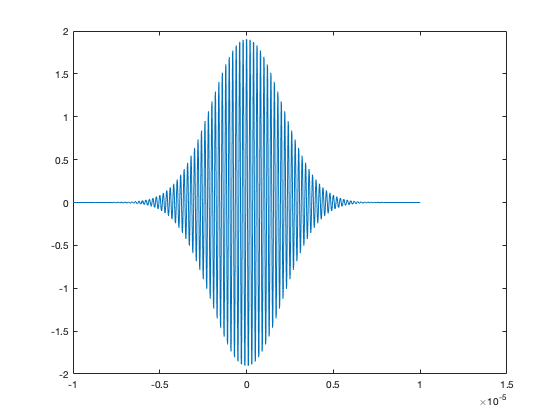

t = linspace(-1e-5, 1e-5, 1000); % niet aanpassen! tfm is hiervan afhankelijk
plot(t,wave(2,5e6,t));

c = 7e6;
xref = -5;
zref = 2;
numElements = 64;
elementWidth = 0.53;
pitch = 0.63;
waveInfo = [1, 5e6,t];
materialInfo = [c,xref,zref];
elementInfo = [numElements,elementWidth,pitch];

[fmc,S] = FMC(waveInfo,materialInfo,elementInfo);

## planeScan testing

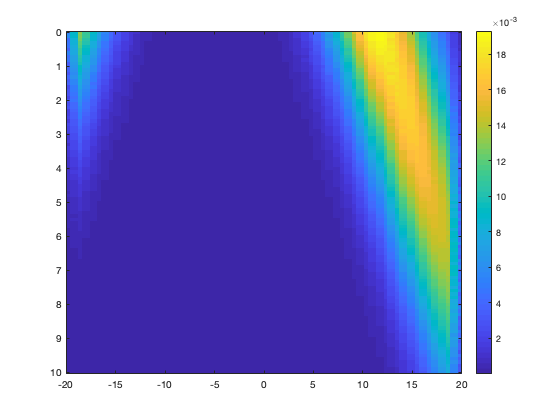

D = 5*pitch;

I = zeros(20);
arraySetup = (-(numElements-1)*pitch/2:pitch:(numElements-1)*pitch/2);
aantalx = 100;% nauwkeurigheid (aantal punten dat je wilt plotten)
aantalz = 100;
xmin = -(numElements-1)*pitch/2;
xmax = (numElements-1)*pitch/2;
zmin = 0.01;
zmax = 10;
stepx = (numElements-1)*pitch/aantalx;
stepz = (zmax-zmin)/aantalz;
for m = 1:aantalx+1
    for n = 1:aantalz+1
        x = xmin + (m-1)*stepx;
        z = zmin + (n-1)*stepz;
        I(n,m) = planeScan(fmc, t, x, z, D, c, arraySetup);
    end
end
imagesc(xmin:stepx:xmax, (zmin:stepz:zmax), I)
colorbar

## sectorScan testing

I = zeros(20);
arraySetup = (-(numElements-1)*pitch/2:pitch:(numElements-1)*pitch/2);
aantalx= 20;% nauwkeurigheid (aantal punten dat je wilt plotten)
aantalz= 20;
xmin = -(numElements-1)*pitch/2;
xmax = (numElements-1)*pitch/2;
zmin = 0.05;
zmax = 10;
stepx = (numElements-1)*pitch/aantalx;
stepz = (zmax-zmin)/aantalx;
for m = 1:aantalx+1
    for n = 1:aantalz+1
        x = xmin + (m-1)*stepx;
        z = zmin + (n-1)*stepz; 
        I(n,m) = sectorScan(fmc,t, x, z, c, arraySetup); % nog probleem omdat time soms negatief wordt...
    end
end
imagesc(xmin:stepx:xmax,zmin:stepz:zmax,I)
colorbar

## focusedScan testing

D = 5*pitch;

I = zeros(20);
arraySetup = (-(numElements-1)*pitch/2:pitch:(numElements-1)*pitch/2);
aantalx= 20;% nauwkeurigheid (aantal punten dat je wilt plotten)
aantalz= 20;
xmin = -(numElements-1)*pitch/2;
xmax = (numElements-1)*pitch/2;
zmin = 0.05;
zmax = 1;
stepx = (numElements-1)*pitch/aantalx;
stepz = (zmax-zmin)/aantalx;
for m = 1:aantalx+1
    for n = 1:aantalz+1
        x = xmin + (m-1)*stepx;
        z = zmin + (n-1)*stepz; 
        I(n,m) = focusedScan(fmc, t, x, z, D, c, arraySetup);
    end
end
imagesc(xmin:stepx:xmax,zmin:stepz:zmax,I)
colorbar

## TFM testing

I = zeros(20);
arraySetup = (-(numElements-1)*pitch/2:pitch:(numElements-1)*pitch/2);
aantalx= 20;% nauwkeurigheid (aantal punten dat je wilt plotten)
aantalz= 20;
xmin = -(numElements-1)*pitch/2;
xmax = (numElements-1)*pitch/2;
zmin = 0.05;
zmax = 1;
stepx = (numElements-1)*pitch/aantalx;
stepz = (zmax-zmin)/aantalx;
for m = 1:aantalx+1
    for n = 1:aantalz+1
        x = xmin + (m-1)*stepx;
        z = zmin + (n-1)*stepz;
        I(n,m) = tfm(fmc,t, x, z, c, arraySetup);
    end
end
imagesc(xmin:stepx:xmax,zmin:stepz:zmax,I)
colorbar